clear;
clc;

input_workspace = "assets\Wasatch\Result\";
output_workspace = "assets\Wasatch\Result\";
basins_id_list = load(fullfile(input_workspace, "basins_id_list.txt"))';

% 定义变量名
names = ["basin_id", "HI", "SLK", "Re", "AF", "BS", "VF", "Iat"];
% 初始化结果存储
result_data = [];

% 用户选择计算的指数
disp("请选择要计算的指数：");

请选择要计算的指数：


流域ID为: 3


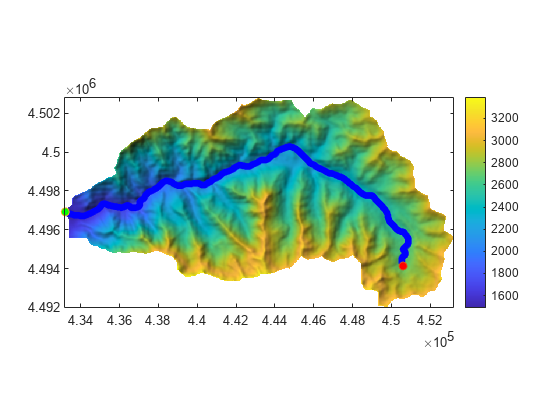

流域ID为: 49


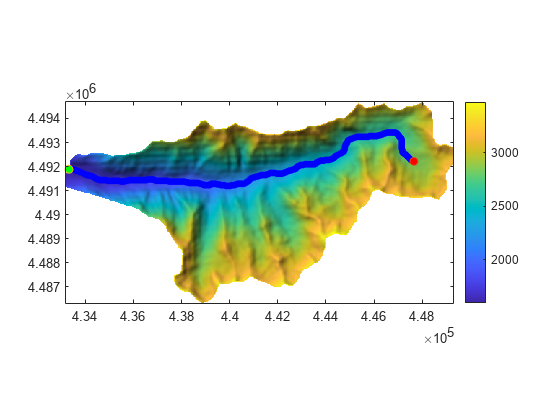

流域ID为: 54


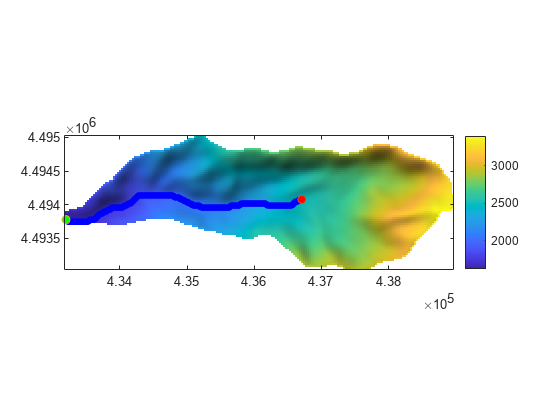

calc_HI = input("是否计算 HI 值？(1: 是, 0: 否)：");
calc_HC = input("是否计算 HC 作图？(1: 是, 0: 否): ");
calc_SLK = input("是否计算 SLK 值？(1: 是, 0: 否)：");
calc_Re = input("是否计算 Re 值？(1: 是, 0: 否)：");
calc_AF = input("是否计算 AF 值？(1: 是, 0: 否)：");
calc_BS = input("是否计算 BS 值？(1: 是, 0: 否)：");
calc_VF = input("是否计算 VF 值？(1: 是, 0: 否)：");

if calc_HC
    % 初始化画布
    hc = figure('Name', 'Hypsometric Curves');
    % 生成颜色序列
    num_basins = length(basins_id_list);
    color_map = lines(num_basins);
    i = 1;
end

for basin_id = basins_id_list
    dem_file_path = fullfile(input_workspace, "basins", strcat("basin_", num2str(basin_id)), strcat("basin_", num2str(basin_id), ".tif"));

    % 检查文件是否存在
    if ~isfile(dem_file_path)
        error('DEM 文件路径无效：%s', dem_file_path);
    end

    % 加载DEM
    dem = fillsinks(GRIDobj(dem_file_path));

    % 展示DEM
    figure;
    imageschs(dem);

    % 计算流向
    flow_direction = FLOWobj(dem);

    disp("流域ID为: " + num2str(basin_id));
    threshold = input("请输入该流域启动河流所需的最小上游区域（单位为像素）个数：");

    % 提取主干道
    main_stream = trunk(STREAMobj(flow_direction, 'minarea', threshold));
    [main_stream_x, main_stream_y] = STREAMobj2XY(main_stream);

    hold on;
    plot(main_stream, 'Color', 'b', 'LineWidth', 5);
    scatter(main_stream_x(1), main_stream_y(1), 'MarkerFaceColor', 'r');
    scatter(main_stream_x(end-1), main_stream_y(end-1), 'MarkerFaceColor', 'g');
    hold off;

    % 初始化指数
    HI_index = NaN;
    SLK_index = NaN;
    Re_index = NaN;
    AF_index = NaN;
    BS_index = NaN;
    VF_index = NaN;

    % 计算选定的指数
    if calc_HI
        HI_index = ttb_calculate_hi_index(dem);
    end
    if calc_SLK
        SLK_index = ttb_calculate_slk_index(dem, main_stream);
    end
    if calc_Re
        Re_index = ttb_calculate_re_index(dem, main_stream);
    end
    if calc_AF
        AF_index = ttb_calculate_af_index(dem, main_stream, false);
    end
    if calc_BS
        BS_index = ttb_calculate_bs_index(dem, main_stream, false);
    end
    if calc_VF
        v_fw_min = input("请输入河道宽度最小值：");
        v_fw_max = input("请输入河谷宽度最大值：");
        nbin = input("请输入 VF 需要采集的点个数：");
        VF_index = ttb_calculate_vf_index(dem, main_stream, v_fw_min, v_fw_max, nbin, false);
    end

    % 输出 HC plot
    if calc_HC
        figure(hc);
        hold on;
        nbin = input("请输入 HC 需要采集的点个数：");
        [normalized_area, normalized_elevation] = hypscurve(dem, nbin);
        normalized_elevation = normalize(normalized_elevation', 'range', [0, 1])';
        normalized_area = normalize(normalized_area', 'range', [0, 1])';
        plot(normalized_area, normalized_elevation, 'Color', color_map(i, :), ...
             'DisplayName', sprintf('Basin %d', basin_id));
        i = i + 1;
        xlabel("Normalized Area (a/A)");
        ylabel("Normalized Elevation (h/H)");
        box on;
    end

    % 动态计算 Iat
    Iat = 0;
    Iat_count = 0; % 记录参与计算的指标数量

    if calc_HI
        Iat = Iat + (HI_index > 0.6) + 2 * (HI_index >= 0.35 && HI_index <= 0.6) + 3 * (HI_index < 0.35);
        Iat_count = Iat_count + 1;
    end
    if calc_SLK
        Iat = Iat + (SLK_index > 3.7) + 2 * (SLK_index >= 2.5 && SLK_index <= 3.7) + 3 * (SLK_index < 2.5);
        Iat_count = Iat_count + 1;
    end
    if calc_Re
        Iat = Iat + (Re_index < 0.5) + 2 * (Re_index >= 0.5 && Re_index <= 0.75) + 3 * (Re_index > 0.75);
        Iat_count = Iat_count + 1;
    end
    if calc_AF
        Iat = Iat + (AF_index <= 0.5) + 2 * (AF_index > 0.5 && AF_index < 1.0) + 3 * (AF_index >= 1.0);
        Iat_count = Iat_count + 1;
    end
    if calc_BS
        Iat = Iat + (BS_index > 2.3) + 2 * (BS_index >= 1.5 && BS_index <= 2.3) + 3 * (BS_index < 1.5);
        Iat_count = Iat_count + 1;
    end
    if calc_VF
        Iat = Iat + (VF_index <= 0.5) + 2 * (VF_index > 0.5 && VF_index < 1.0) + 3 * (VF_index >= 1.0);
        Iat_count = Iat_count + 1;
    end

    if Iat_count > 0
        Iat = Iat / Iat_count;
    else
        Iat = NaN; % 如果没有参与计算的指标，设置 Iat 为 NaN
    end

    % 将计算结果存入数据矩阵
    result_data = [result_data; basin_id, HI_index, SLK_index, Re_index, AF_index, BS_index, VF_index, Iat];
end


% 将数据写入 Excel 文件
result_table = array2table(result_data, 'VariableNames', names);
table_file_path = fullfile(output_workspace, "indices.xlsx");
writetable(result_table, table_file_path, 'WriteMode', 'replacefile');
disp("结果已保存为 Excel 文件！");

结果已保存为 Excel 文件！


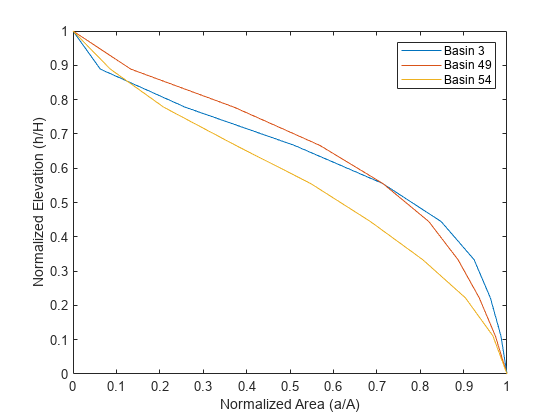


% 设置统一图例与坐标轴标签
legend('show');
xlabel("Normalized Area (a/A)");
ylabel("Normalized Elevation (h/H)");
box on;
hold off;
saveas(hc, fullfile(output_workspace, "HC.png"));